# # 2024-08-20 - Computer Vision (CV) Posterior Analyses 

addpath(genpath('helpers'));
addpath('External'); % Not recur

img_path = fullfile("C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale");
%img_path = fullfile("/home/halechr/Desktop/_temp_individual_posteriors/2024-08-21/laps/greyscale");
img_path

img_path = "C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale"

imdsTrain = imageDatastore(img_path,'IncludeSubfolders',true);
imdsTrain.readall("UseParallel",true)

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


ans = 84×1 cell array
    {1024×1185 uint8}
    {1024×5209 uint8}
    {1024×3844 uint8}
    {1024×4814 uint8}
    {1024×4634 uint8}
    {1024×5048 uint8}
    {1024×3341 uint8}
    {1024×5245 uint8}
    {1024×6413 uint8}
    {1024×4060 uint8}
    {1024×4473 uint8}
    {1024×1832 uint8}
    {1024×4401 uint8}
    {1024×3269 uint8}
    {1024×4113 uint8}
    {1024×3844 uint8}

processed_images = batchposterior_batch_import_imfcn(imdsTrain);

PASSED:C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale\p_x_given_n[0].png
PASSED:C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale\p_x_given_n[31].png
PASSED:C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale\p_x_given_n[35].png
PASSED:C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale\p_x_given_n[10].png
PASSED:C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale\p_x_given_n[20].png
PASSED:C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale\p_x_given_n[28].png
PASSED:C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale\p_x_given_n[24].png
PASSED:C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08

%imageBatchProcessor(imdsTrain)

processed_images

processed_images = 84×5 table
            bw                  imgray                seg_bw            seg_maskedImage                                                                fileName                                                           
    ___________________    _________________    ___________________    _________________    ______________________________________________________________________________________________________________________________
    {1024×1185 logical}    {1024×1185 uint8}    {1024×1185 logical}    {1024×1185 uint8}    {'C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\_temp_individual_posteriors\2024-08-21\laps\greyscale\p_x_given_n[0].png' }
    {1024×5209 logical}    {1024×5209 uint8}    {1024×5209 logical}    {1024×5209 uint8}    {'C:\Users\pho\repos\Spike3DWorkEnv\Spike3D\output\

## Image Processing Interactive

epoch_idx =17

epoch_idx = 17

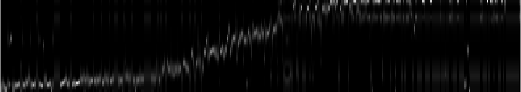

%im = processed_images.seg_bw{epoch_idx};
im = processed_images.imgray{epoch_idx};
bw = processed_images.seg_bw{epoch_idx};

figure(1); imshow(im);

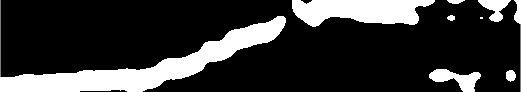

figure(2); imshow(bw);

% imP = ImToPolar(im, 0.6, 1, 40, 200);

Unrecognized function or variable 'ImToPolar'.

% figure(2); imshow(imP);
% imR = PolarToIm(imP, 0.6, 1, 250, 250);
% figure(3); imshow(imR);
% rMin = 0.25; rMax = 0.8;

% Rotation invariant image moments
%moment(im)
inv_moments = Hu_Moments(im)

inv_moments = 1×7 uint8 row vector
   114   255   255   255     0   255   255


%eta = SI_Moment(im, bw)
%cen_mmt = Centr_Moment(im,bw)
%F = IMOMENTS(im)


% https://raphael.candelier.fr/?blog=Image%20Moments

E = IM.get_ellipse(bw)                % Compute the equivalent ellipse

E = struct with fields:
      m00: 1210658
      m10: 3.3647e+09
      m01: 652141443
      m11: 1.3385e+12
      m02: 5.0073e+11
      m20: 1.2407e+13
        x: 2.7793e+03
        y: 538.6669
    theta: 2.9839
        w: 494.7105
        l: 3.2160e+03
       x1: -359.0257
       y1: 1.0377e+03
       x2: 5.9176e+03
       y2: 39.6514

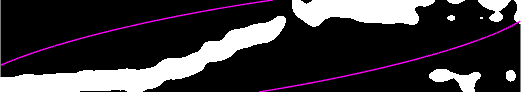

% Draw the ellipse overlaying the image:
imshow(bw)
hold on
IM.draw_ellipse(E, 'color', 'm')

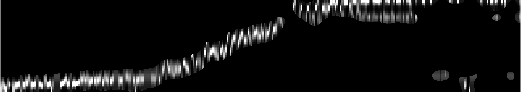

[BW, blurredImg, maskedImage] = fn_segimg_replay_connect(im);
imshow(blurredImg)

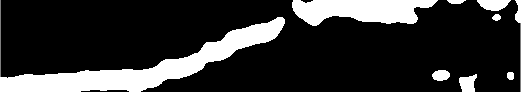

imshow(BW)

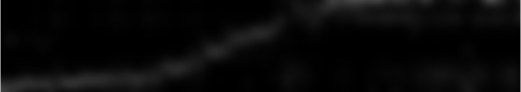

imshow(maskedImage)

imshow(BW)

### Post-hoc Processing of processed_images

% Read the sample image in
im = imgray{1}; % imread('shapessm.jpg');
im

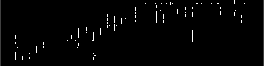


% Find edges using the Canny operator with hysteresis thresholds of 0.1
% and 0.2 with smoothing parameter sigma set to 1.
edgeim = edge(im,'canny', [0.1 0.2], 1);

figure(1), imshow(edgeim);

% Link edge pixels together into lists of sequential edge points, one
% list for each edge contour. A contour/edgelist starts/stops at an 
% ending or a junction with another contour/edgelist.
% Here we discard contours less than 10 pixels long.

[edgelist, labelededgeim] = edgelink(edgeim, 10);

Unrecognized function or variable 'edgelink'.


% Display the edgelists with random colours for each distinct edge 
% in figure 2

drawedgelist(edgelist, size(im), 1, 'rand', 2); axis off  

% Fit line segments to the edgelists
tol = 2;         % Line segments are fitted with maximum deviation from
	     % original edge of 2 pixels.
seglist = lineseg(edgelist, tol);

Not enough input arguments.
Error in edgelist (line 60)
    if direction == 0


% Draw the fitted line segments stored in seglist in figure window 3 with
% a linewidth of 2 and random colours
drawedgelist(seglist, size(im), 2, 'rand', 3); axis off


S = fastradial(im, [1 3 5], 2, 0)

Unrecognized function or variable 'fastradial'.

# Mean square displacement analysis of particle trajectories

% ma = msdanalyzer(2, 'µm', 's')

# Tracking

% SPACE_UNITS = 'µm';
% TIME_UNITS = 's';
% 
% N_PARTICLES = 1;
% N_TIME_STEPS = 1861;
% %N_DIM = 2; % 2D
% N_DIM = 1; % 1D
% 
% % Typical values taken from studies of proteins diffusing in membranes:
% % Diffusion coefficient
% D  = 1e-3; % µm^2/s
% % Time step between acquisition; fast acquisition!
% dT = 0.05; % s,
% 
% % Area size, just used to disperse particles in 2D. Has no impact on
% % analysis.
% SIZE = 2; % µm
% k = sqrt(2 * D * dT);

% tracks = cell(N_PARTICLES, 1);
% 
% for i = 1 : N_PARTICLES
% 
%     % Time
%     time = (0 : N_TIME_STEPS-1)' * dT;
% 
%     % Initial position
%     X0 = SIZE .* rand(1, N_DIM);
% 
%     % Integrate uncorrelated displacement
%     dX = k * randn(N_TIME_STEPS, N_DIM);
%     dX(1, :) = X0;
%     X = cumsum(dX, 1);
% 
%     size(time)
%     size(X)
%     % Store
%     tracks{i} = [time X];
% 
% end
% clear i X dX time X0

% tracks = cell(N_PARTICLES, 1);
% tracks{1} = flat_tracks;

% ma = msdanalyzer(N_DIM, SPACE_UNITS, TIME_UNITS);
% % This does not work:
% %ma.addAll(tracks);
% 
% % This works:
% ma = ma.addAll(tracks);
% 
% % Indeed:
% disp(ma)